# Gráficas tridimensionales

## Gráfica lineal tridimensional con función `plot3`

La función `plot3` es similar a la función `plot`, la diferencia radica en que esta nueva función recibe 3 vectores para realizar la gráfica en 3 dimensiones.

clear

x = linspace(0,10*pi,1000);
y = cos(x);
z = sin(x);

plot3(x,y,z)
title 'Un resorte'
xlabel 'Ángulo'
ylabel 'cos(x)'
zlabel 'sin(x)'
grid

Como se observa en el código, se puede modificar las mismas características para que la función `plot`, añadiéndose la posibilidad de editar también el eje **z**.

**Nota:** La función `plot3` utiliza la regla de la mano derecha para generar el sistema de coordenadas.

### Función `comet3`

Una función curiosa es la `comet3`. Esta función genera la misma gráfica que la función `plot3`, pero la va "dibujando" en lugar de presentarla graficada en su totalidad.

comet3(x,y,z)

**Nota:** Para gráficas bidimensionales se utiliza la función `comet`.

### Gráficas de superficie

Las gráficas de superficie permiten representar datos como una superficie.

#### Gráficas `mesh`

Existen muchas formas de usar las gráficas de malla (`mesh`). Por ejemplo, se pueden utilizar para dar un buen efecto a una matriz bidimensional sencilla `mxn`. En esta aplicación, el valor de la matriz representa los valores para de **z** en la gráfica.

Para esta, y muchas otras aplicaciones, se utiliza la función `mesh`.

clear

z = [
    1:10
    2:2:20
    3:12
    ]

mesh(z)
xlabel 'Eje x'
ylabel 'Eje y'
zlabel 'Eje z'

Como ya se dijo, la gráfica es una malla creada a partir de la matriz `z`. Pero, ¿de dónde toma los valores representar **x** y **y**? Pues bien, si sólo se ingresa un argumento a la función `mesh`,

- **x** tomará como valores los índices de las columnas, es decir, para graficar `z` se tomó **x** = `1:10` (número de columnas de `z`).

- **y** tomará como valores los índices de las filas, es decir, para graficar `z` se tomó **y** = `1:3` (número de filas de `z`).

Entonces, para graficar el elemento en la posición $z_{1,5}=5$ el punto graficado es $P(x,y,z)=(5,1,5)$.

Sin embargo, también se le puede pasar a la función 3 argumentos que serían los vectores **x**, **y** y **z**.

x = linspace(1,50,10);
y = linspace(500,1000,3);

mesh(x,y,z)
xlabel 'Eje x'
ylabel 'Eje y'
zlabel 'Eje z'

Se debe tener en cuenta las siguientes consideraciones cuando se ingresan los 3 argumentos a la función `mesh`:

- El vector **x** debe tener el mismo número de elementos que el número de columnas en el vector **z**.

- El vector **y** debe tener el mismo número de elementos que el número de filas en el vector **z**.

#### Gráficas `surf`

Las gráficas `surf` son similares a las gráficas `mesh`, pero `surf` crea una superficie tridimensional colorida en lugar de una malla. Los colores varían con el valor de **z**.

Las mismas consideraciones que se hicieron para la funcion `mesh` cuando se ingresa un solo argumento, o varios, son válidas para la función `surf`.

clear

z = [
    1:10
    2:2:20
    3:12
    ];
x = linspace(1,50,10);
y = linspace(500,1000,3);

surf(x,y,z)
xlabel 'Eje x'
ylabel 'Eje y'
zlabel 'Eje z'

#### Comando `shading`

El comando `shading` controla el sombreado de una gráfica. Existen 3 tipos de sobreado: `faceted` (por defecto), `flat` e `interp`.

El sombreado `interp` interpola valores de **z** para crear una gama de colores.

surf(x,y,z)
shading interp

El sobreado `flat` genera un sombreado plano sin retícula.

surf(x,y,z)
shading flat

#### Comando `colormap`

El comando `colormap` controla el esquema de color usado en la gráfica.

surf(x,y,z)
colormap gray 

A continuación se muestran algunos colores disponibles:

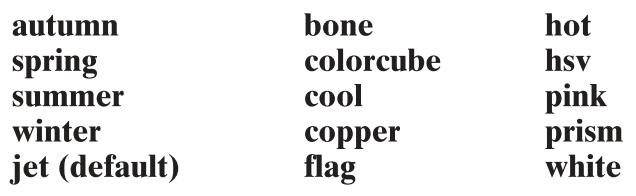

#### Ejemplo

Es posible crear superficies más complejas calculando los valores de **z**.

clear

x = -2:.2:2;
y = x;
[X, Y] = meshgrid(x,y);
Z = X.*exp(-X.^2 - Y.^2);

subplot(1,2,1)
    mesh(X,Y,Z)
    title 'Gráfica mesh', xlabel 'Eje x', ylabel 'Eje y', zlabel 'Eje z'

subplot(1,2,2)
    surf(X,Y,Z)
    title 'Gráfica surf', xlabel 'Eje x', ylabel 'Eje y', zlabel 'Eje z'

### Gráficas de contorno

Las gráficas de contorno son representaciones bidiomensionales de superficies tridimensionales. Ejemplo: curvas de nivel.

Mediante la función `contour` se las puede generar.

clear

x = -2:.2:2;
y = x;
[X, Y] = meshgrid(x,y);
Z = X.*exp(-X.^2 - Y.^2);

contour(X,Y,Z)
title 'Gráfica de contorno', xlabel 'Eje x', ylabel 'Eje y', zlabel 'Eje z'

La función `surfc` genera una gráfica de superficie y de contrno al mismo tiempo.

surfc(X,Y,Z)
title 'Combinación de gráficas de superficie y de contorno'
xlabel 'Eje x', ylabel 'Eje y', zlabel 'Eje z'

### Gráficas en pseudocolor

Las gráficas en pseudocolor son similares a las gráficas de contorno, excepto que, en lugar de líneas que resaltan un contorno específico, se genera un mapa bidimensional sombreado sobre una retícula.

MATLAB incluye una función muestra llamada `peaks` (detallada en el subcapítulo 1: **sc1**) que genera las matrices **x**, **y** y **z** de una interesante superficie que parece una montaña.

La función `pcolor` genera este tipo de gráficas.

clear

[x, y, z] = peaks;

subplot(2,2,1)
    pcolor(x,y,z)
subplot(2,2,2)
    pcolor(x,y,z)
    shading interp
subplot(2,2,3)
    pcolor(x,y,z)
    shading interp
    hold on
    contour(x,y,z,'k')      % Se grafica los contornos en color negro para diferenciarlos.
subplot(2,2,4)
    contour(x,y,z)          % Gráfica de contorno para comparar.

# Edición de gráficas desde la barra de menú

Desde la barra de menú de cada figura es posible modificar las características, apariencia, etc.; de las gráficas.

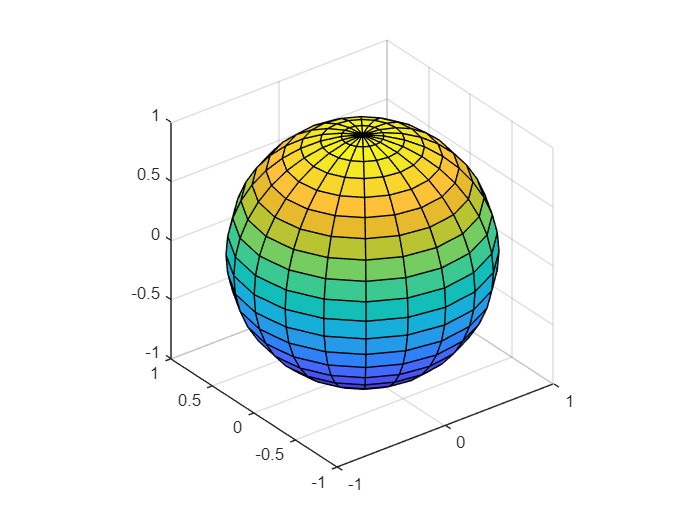

sphere      % Gráfica de muestra de MATLAB.
axis equal

Si ejecuta el anterior código en la ventana de comandos se abrirá la ventada con esa figura. En la barra de menú de esa ventana puede modificar lo que desee de la gráfica para posteriormente guardarla.

**Nota:** Todo los cambios que se hagan desde la barra de menú se borrarán al correr el código nuevamente.

**Nota:** También es posible exportar la gráfica en distintos formatos para usarse en otros lugares desde la barra de menú.

**Recomendación:** O bien puede guardar la figura con los cambios que se hayan hecho, o bien se puede obtener el código de esos cambios. En el menú **File** está la opción **Generate Code** con la que se obtiene el código.

# Tabla resumen de gráficas en 3D

A continuación, se detallan las funciones estudiadas en este subcapítulo para realizar gráficas en el espacio: